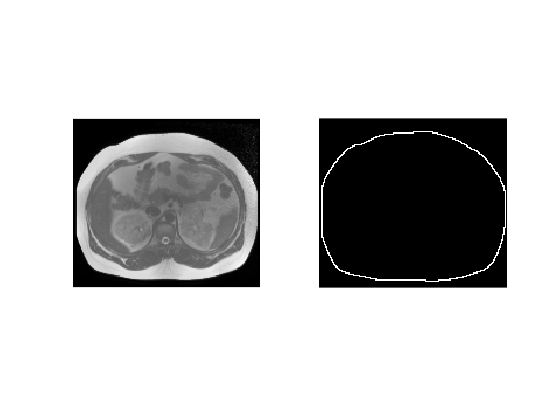

%Load the dataset and show the images with their segmentations
data1 = load("dataForNN_foreBorder_clip0.mat");
data2 = load("dataForNN_foreBorder_clip1.mat");
data3 = load("dataForNN_inside_clip0.mat");

figure();
subplot(1, 2, 1), imshow(data1.trainingImage);
subplot(1, 2, 2), imshow(data1.trainingSegmentation);

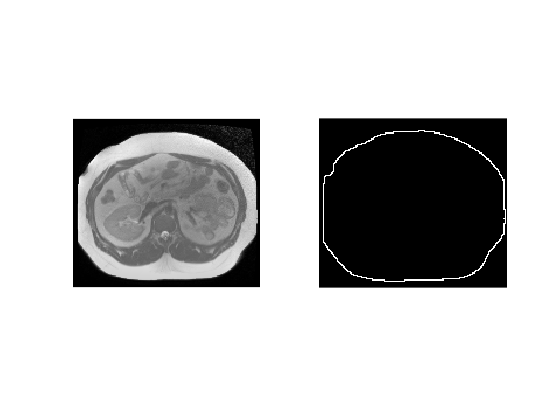


figure();
subplot(1, 2, 1), imshow(data1.testImage, []);
subplot(1, 2, 2), imshow(data1.testSegmentation, []);

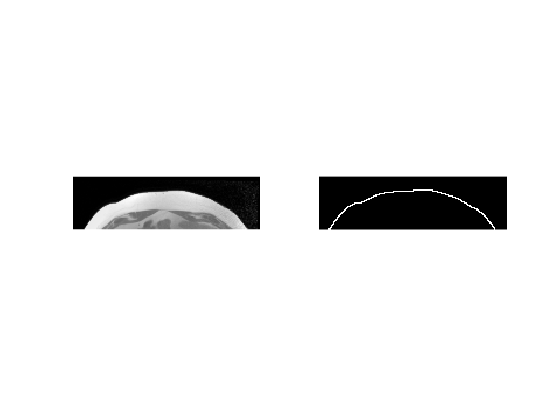



figure();
subplot(1, 2, 1), imshow(data2.trainingImage, []);
subplot(1, 2, 2), imshow(data2.trainingSegmentation, []);

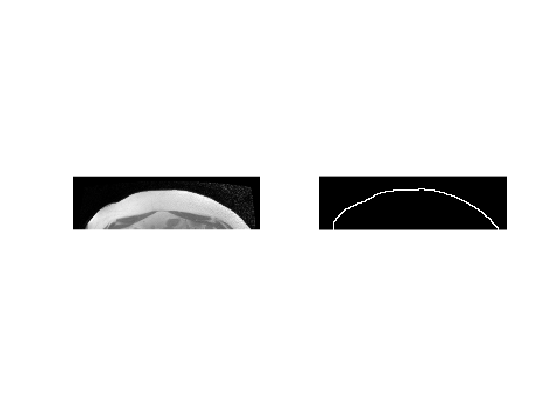


figure();
subplot(1, 2, 1), imshow(data2.testImage, []);
subplot(1, 2, 2), imshow(data2.testSegmentation, []);

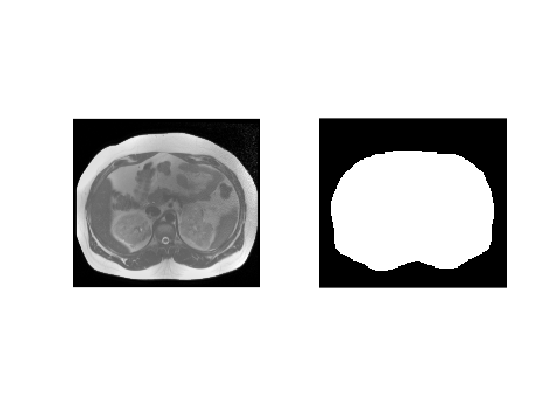


figure();
subplot(1, 2, 1), imshow(data3.trainingImage, []);
subplot(1, 2, 2), imshow(data3.trainingSegmentation, []);

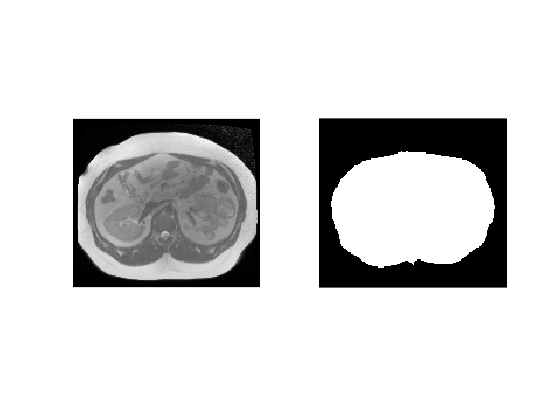


figure();
subplot(1, 2, 1), imshow(data3.testImage, []);
subplot(1, 2, 2), imshow(data3.testSegmentation, []);

%Define Beta vector, cost vector, stepsize and the training/testing image
Beta = zeros([1, 6]);
ImTrain = data3.trainingImage;
ImSegm = data3.trainingSegmentation;
stepSize = 0.005;
costVector = zeros([1 5000]);

for k = 1:5000
    randPerm = randperm(length(ImTrain(:)), 200);
    ImTrainRes = zeros(size(ImTrain));
    for j = 1:6
        ImTrainRes = ImTrainRes + Beta(j) * BasisFun(ImTrain, j);
    end
    ImTrainRes = Sigmoid(ImTrainRes);
    costVector(k) = getCost(ImTrainRes, ImSegm, randPerm);
    delta = 0.001;
    Gradient = zeros(size(Beta));
    for i = 1:length(Beta)
        newBeta = Beta;
        newBeta(i) = newBeta(i) + delta;
        ImTrainRes = zeros(size(ImTrain));
        for j = 1:6
            ImTrainRes = ImTrainRes + newBeta(j) * BasisFun(ImTrain, j);
        end
        ImTrainRes = Sigmoid(ImTrainRes);
        newCost = getCost(ImTrainRes, ImSegm, randPerm);
        Gradient(i) = (newCost - costVector(k)) / delta;
    end
    Beta = Beta - stepSize * Gradient;
end
ImTrainRes = zeros(size(ImTrain));
for i = 1:6
    ImTrainRes = ImTrainRes + Beta(i) * BasisFun(ImTrain, i);
end

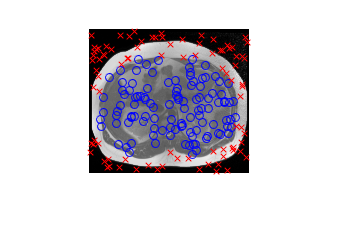

%Obtain indices of the 200 random points from the last iteration where the segmentation is 1/0
randPermTrue = randPerm(ImSegm(randPerm) == 1);
randPermFalse = randPerm(ImSegm(randPerm) == 0);
%Plot the points on the image
figure();
imshow(data3.trainingImage)
hold on;
plot(idivide(int16(randPermTrue), size(data3.trainingImage, 1)), mod(randPermTrue, size(data3.trainingImage, 1)), 'ob')
plot(idivide(int16(randPermFalse), size(data3.trainingImage, 1)), mod(randPermFalse, size(data3.trainingImage, 1)), 'xr')

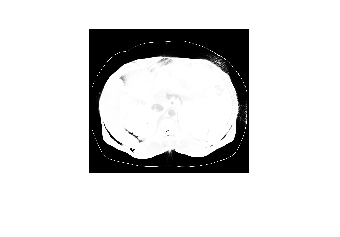

%Plot the posterior of the training image
figure();
imshow(Sigmoid(ImTrainRes), [])

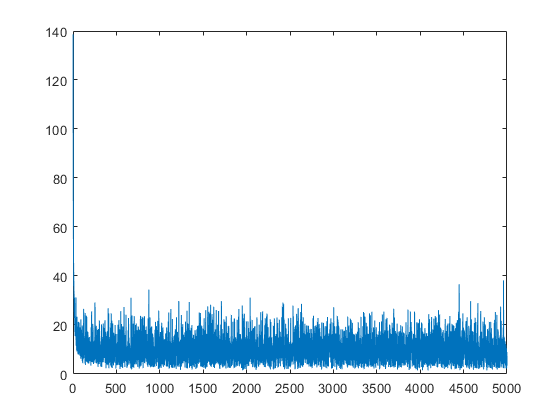

%Plot the progression of the cost vector throughout the iterations
figure();
plot(costVector);

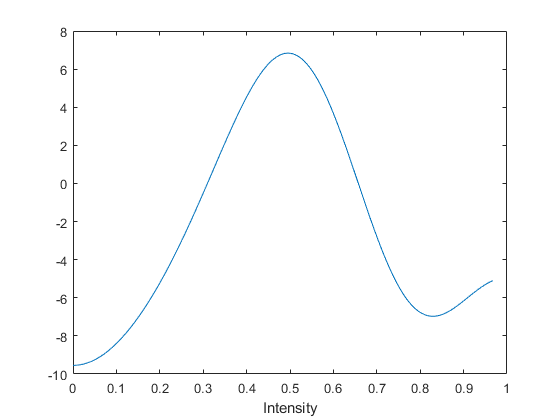

%Plot the value of a = sum(beta * basisFunction) across the intensity
%values
X = 0:0.001:max(ImTrain(:));
Y = Beta(1) * BasisFun(X, 1);
for i = 2:6
    Y = Y + Beta(i) * BasisFun(X, i);
end
figure();
plot(X,Y)
xlabel("Intensity")

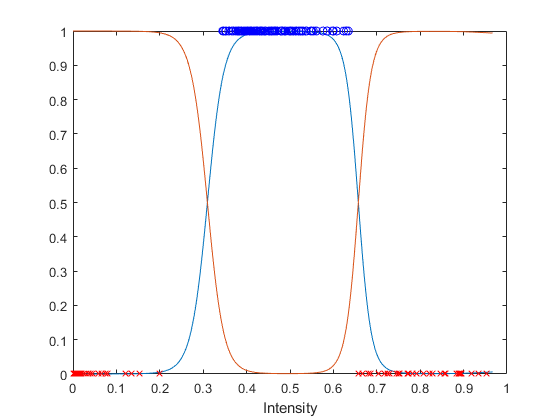

figure();
%Plot the squashed sigma(a) and add the selected points from the previous
%iteration
plot(X, Sigmoid(Y))
hold on;
plot(X, 1 - Sigmoid(Y))
plot(ImTrain(randPermTrue), 1, 'ob')
plot(ImTrain(randPermFalse), 0, 'xr')
xlabel("Intensity")
hold off;

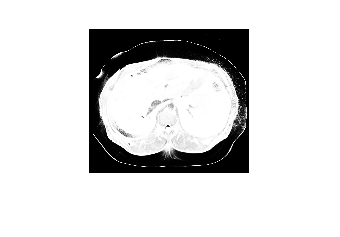

%Apply the model to the test image
ImTest = data3.testImage;
ImTestRes = zeros(size(ImTest));
for i = 1:6
    ImTestRes = ImTestRes + Beta(i) * BasisFun(ImTest, i);
end
ImTestRes = Sigmoid(ImTestRes);
imshow(ImTestRes)

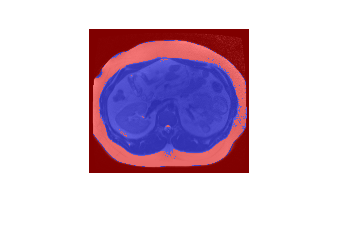

Blue = (ImTestRes > 0.5);
Red = (ImTestRes <= 0.5);
rgb = zeros(size(ImTest));
rgb(:, :, 1) = Red;
rgb(:, :, 3) = Blue;
imshowpair(ImTest, rgb, 'blend')

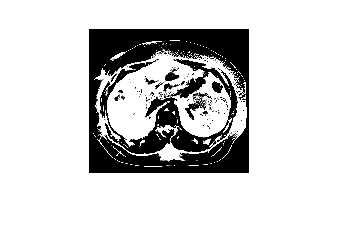

%Replace the test image with a new one with d=d^1.3 
ImTestNew = ImTest.^1.3;
figure();
subplot(1, 2, 1), imshow(ImTest), title("Original test image");
subplot(1, 2, 2), imshow(ImTestNew), title("Modified test image");
ImTestNewRes = zeros(size(ImTestNew));
for i = 1:6
    ImTestNewRes = ImTestNewRes + Beta(i) * BasisFun(ImTestNew, i);
end
figure();
imshow(ImTestNewRes)

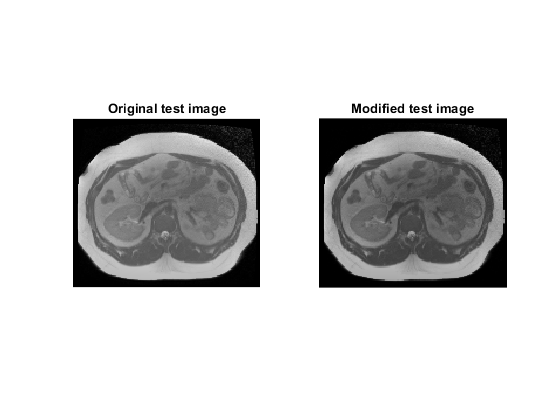

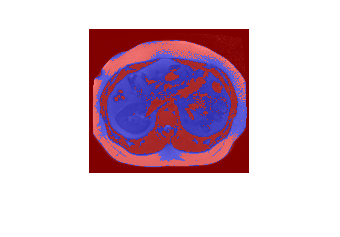

rgb(:, :, 1) = ImTestNewRes <= 0.5;
rgb(:, :, 3) = ImTestNewRes > 0.5;
figure();
imshowpair(ImTestNew, rgb, 'blend');

%Apply the convolutional neural network
%Define the beta vector, weights
M = 6;
p = 1;
maxIter = 7500;
Beta = zeros([1, M]);
ImTrain = data3.trainingImage;
ImSegm = data3.trainingSegmentation;
stepSize = 0.025;
costVector = zeros([1 maxIter]);
weights = normrnd(0, 1, M, p + 1);
for k = 1:maxIter
    %Take a random sample of points from the image
    randPerm = randperm(length(ImTrain(:)), 200);
    %Construct the segmentation
    ImTrainRes = zeros(size(ImTrain));
    for j = 1:M
        ImTrainRes = ImTrainRes + Beta(j) * AdBasisFun(ImTrain, weights, j, p);
    end
    ImTrainRes = Sigmoid(ImTrainRes);
    %Compute the cost given the computed segmentation
    costVector(k) = getCost(ImTrainRes, ImSegm, randPerm);
%     if (k < 5)
%         disp("The cost of this iteration is:")
%         disp(costVector(k))
%     end
    delta = 0.001;
    %Convert the beta and weights into a single vector
    weights2 = weights';
%     if (k < 5)
%         disp("weights vector is:")
%         disp(weights)
%         disp("Transposed weights vector is:")
%         disp(weights2)
%     end
    Params = [Beta' ; weights2(:)];
%     if (k < 5)
%         disp("Parameter vector is")
%         disp(Params)
%     end
    Gradient = zeros(size(Params));
    for i = 1:length(Params)
        newParams = Params;
        newParams(i) = newParams(i) + delta;
        %Convert the parameter vector back into beta and weights
        newBeta = newParams(1:M);
        newWeights = reshape(newParams((M + 1):end), size(weights2))';
%         if (k < 5 && i == length(Params))
%             disp("New weights vector:")
%             disp(newWeights)
%         end
        %Construct the segmentation given one of the parameters slightly
        %adjusted
        ImTrainRes = zeros(size(ImTrain));
        for j = 1:M
            ImTrainRes = ImTrainRes + newBeta(j) * AdBasisFun(ImTrain, newWeights, j, p);
        end
        ImTrainRes = Sigmoid(ImTrainRes);
        newCost = getCost(ImTrainRes, ImSegm, randPerm);
        Gradient(i) = (newCost - costVector(k)) / delta;
%         if (k == 1)
%             disp("Gradient is:")
%             disp(Gradient)
%         end
    end
%     if (k < 10)
%         disp("Full Gradient is:")
%         disp(Gradient)
%     end
    %Update the parameters
    Params = Params - stepSize * Gradient;
    Beta = Params(1:M)';
    weights = reshape(newParams((M + 1):end), size(weights2))';
    if (k < 5 || k > maxIter - 5)
        disp("Weights are:")
        disp(weights)
    end
end

Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    0.5865



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    0.5875



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    0.5885



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    0.5895



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    8.0815



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    8.0825



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    8.0835



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    8.0845



Weights are:


   -1.7644   -0.8918
    0.6456   -0.3536
   -0.4757   -1.3704
    0.3936    1.4141
    0.7763   -1.2573
   -0.8418    8.0855



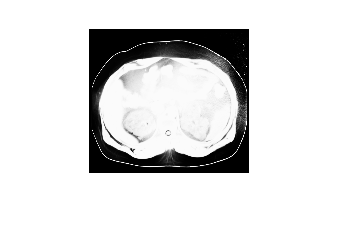

ImTrainRes = zeros(size(ImTrain));
for i = 1:M
    ImTrainRes = ImTrainRes + Beta(i) * AdBasisFun(ImTrain, weights, i, p);
end
ImTrainRes = Sigmoid(ImTrainRes);
imshow(ImTrainRes)

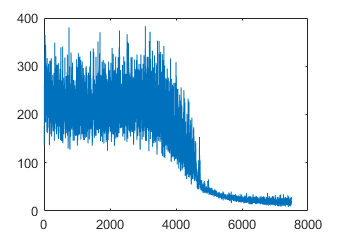

plot(costVector)

costVector(end)

ans = 15.6829

%Some testing section
a = [1 2; 3 4]

a =      1     2
     3     4


1 + 2 * a

ans =      3     5
     7     9


%Define the adaptive basis functions

function B = AdBasisFun(x, w, m, p)
%The following function calculates the value of the 
    if (m == 1)
        B = ones(size(x));
    elseif (p == 1)
        B = Sigmoid(w(m, 1) + w(m, 2) * x);
    end
end